% Define the size of the grid
gridSize = 12;  % Change this value to any desired grid size

% Create the figure and axes
figure;
hold on;
axis equal;
grid on;
set(gca, 'XTick', 0:gridSize, 'YTick', 0:gridSize); % Adjust grid size as needed
xlim([0 gridSize]);
ylim([0 gridSize]);
set(gca, 'YDir', 'reverse'); % Reverse the Y-axis direction

% Define the start point 
xi = 3; % represents the rows
yi = 2; % represents the columns

% Plot start point (opposite because it is according to the axises)
plot(yi, xi, 'go', 'MarkerSize', 10, 'LineWidth', 2);

% Define the object's vertices (square for simplicity)
object_vertices_x = [7, 8, 9, 10, 9, 8];
object_vertices_y = [9, 10, 10, 9, 8 , 8];

% Create the object shape
fill(object_vertices_x, object_vertices_y, 'b', 'FaceAlpha', 0.5);

% Define grasp point 
xf = gridSize - 5; 
yf = gridSize - 2; 

% Check if the grasp point is within the object zone
in_object = inpolygon(xf, yf, object_vertices_x, object_vertices_y);

if in_object
    disp('ERROR: The final point is within the object zone.');
else
    % Plot final point (grasp point)
    plot(xf, yf, 'ro', 'MarkerSize', 10, 'LineWidth', 2);

    % Display grid
    for i = 1:(gridSize-1)
        for j = 1:(gridSize-1)
            plot(i, j, 'ks', 'MarkerSize', 5, 'MarkerFaceColor', 'none');
        end
    end

    % Highlight the grasp point on the object
    plot(xf, yf, 'ms', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'magenta');

    % Create a polygon from the object's vertices
    [xq, yq] = meshgrid(0:gridSize, 0:gridSize);
    in = inpolygon(xq, yq, object_vertices_x, object_vertices_y);

    % Create matrix A representing the 2D space
    A = inf(gridSize + 1, gridSize + 1); % Initialize with inf values

    % Mark the start point in A
    A(yi + 1, xi + 1) = 0; % Starting point set to 0

    % Highlight the cells inside the polygon and update the matrix A
    for i = 1:numel(xq)
        if in(i)
            A(yq(i) + 1, xq(i) + 1) = -1; % Using -1 to represent the object
            fill(xq(i) + [-0.5 0.5 0.5 -0.5], yq(i) + [-0.5 -0.5 0.5 0.5], 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'none');
        end
    end

    % Mark the grasp point in A
    A(yf + 1, xf + 1) = -2;

    % Print the matrix A to the screen
    disp('Matrix A:');
    disp(A);

    % Display the final point (grasp point) in the matrix A
    final_point_value = A(yf + 1, xf + 1);
    disp(['Final point (grasp point) value in A: ', num2str(final_point_value)]);
end

Matrix A:


   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf     0   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf    -1    -1   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf    -1    -1    -1    -1   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf    -2    -1    -1   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   I

Final point (grasp point) value in A: -2



% Initialize unvisit list
s = length(A) - 1;
unvisit = [];

s = (length(A)-1);
for i=2:s
    for j=2:s
        if i == 2 && j == 2
            unvisit = [unvisit ; [i,j] , [i + 1, j] , [0, 0] , [i, j + 1] , [0, 0]];
        
        elseif i == 2 && j == s
            unvisit = [unvisit ; [i,j] , [i + 1, j] , [0 , 0] , [0 , 0] , [i, j-1]];
        
        elseif i == s && j == s
            unvisit = [unvisit ; [i,j] , [0 , 0] , [i-1 , j] , [0 , 0] , [i , j-1]];
        
        elseif i == s && j == 2
            unvisit = [unvisit ; [i,j] , [0, 0] , [i-1 , j] , [i, j + 1] , [0, 0]];
        
        elseif i == 2 
            unvisit = [unvisit ; [i,j] , [i + 1, j] , [0, 0] , [i, j + 1] , [i, j-1]];
        
        elseif i == s 
            unvisit = [unvisit ; [i,j] , [0, 0] , [i-1 , j] , [i, j + 1] , [i, j-1]];
        
        elseif j == 2 
            unvisit = [unvisit ; [i,j] , [i + 1, j] , [i - 1, j] , [i, j + 1] , [0, 0]];
        
        elseif j == s
            unvisit = [unvisit ; [i,j] , [i + 1, j] , [i - 1, j] , [0 , 0] , [i, j - 1]];

        else
            unvisit = [unvisit ; [i,j] , [i + 1, j] , [i - 1, j] , [i , j+1] , [i, j - 1]];

        end
    end 
end

disp(unvisit)

     2     2     3     2     0     0     2     3     0     0
     2     3     3     3     0     0     2     4     2     2
     2     4     3     4     0     0     2     5     2     3
     2     5     3     5     0     0     2     6     2     4
     2     6     3     6     0     0     2     7     2     5
     2     7     3     7     0     0     2     8     2     6
     2     8     3     8     0     0     2     9     2     7
     2     9     3     9     0     0     2    10     2     8
     2    10     3    10     0     0     2    11     2     9
     2    11     3    11     0     0     2    12     2    10
     2    12     3    12     0     0     0     0     2    11
     3     2     4     2     2     2     3     3     0     0
     3     3     4     3     2     3     3     4     3     2
     3     4     4     4     2     4     3     5     3     3
     3     5     4     5     2     5     3     6     3     4
     3     6     4     6     2     6     3     7     3     5
     3     7     4     7


% giving zeroes to all the neighbors that are part of the obstacle 
% giving zeros to the neighbors of the obstacles 
% the relavent elements in A matrix are between 2:6 (include the tips) 
for j = 1:(s-1)^2
    for i = 0:2:8
        a = [unvisit(j , i + 1),unvisit(j , i + 2)];
        if (i==0 && A(a(1),a(2)) == -1) || (i==0 && A(a(1),a(2)) == -2)
            unvisit(j, 3:10) = 0;
            continue
        elseif i == 0 && a(1)== (xi+1) && a(2) == (yi+1)
            continue
        elseif a(1)==0 && a(2) == 0
            continue
        elseif A(a(1),a(2)) == -1 || A(a(1),a(2)) == 0 
            unvisit(j , i + 1) = 0;
            unvisit(j , i + 2) = 0;
        end
    end
end
unvisit;

disp('Updated unvisit:');

Updated unvisit:


disp(unvisit)

     2     2     3     2     0     0     2     3     0     0
     2     3     3     3     0     0     2     4     2     2
     2     4     0     0     0     0     2     5     2     3
     2     5     3     5     0     0     2     6     2     4
     2     6     3     6     0     0     2     7     2     5
     2     7     3     7     0     0     2     8     2     6
     2     8     3     8     0     0     2     9     2     7
     2     9     3     9     0     0     2    10     2     8
     2    10     3    10     0     0     2    11     2     9
     2    11     3    11     0     0     2    12     2    10
     2    12     3    12     0     0     0     0     2    11
     3     2     4     2     2     2     3     3     0     0
     3     3     4     3     2     3     0     0     3     2
     0     0     4     4     2     4     3     5     3     3
     3     5     4     5     2     5     3     6     0     0
     3     6     4     6     2     6     3     7     3     5
     3     7     4     7



% Initialize visit list with the starting point
visit = [xi+1, yi+1];
current_point = visit(end, :);
current_x = current_point(1);
current_y = current_point(2);

% Loop until the final point is found or no path is possible
while true
    % Get the current point
    
    % Check if the final point is reached
    if A(current_y, current_x) == -2
        disp('Final point reached');
        break;
    end
    
    % Find valid neighbors
    % problem place ---------------------------------------------------
    neighbors = [];
    for j = 1:size(unvisit, 1)
        if unvisit(j, 1) == current_x && unvisit(j, 2) == current_y
            for k = 3:2:10
                if unvisit(j, k) ~= 0 && unvisit(j, k+1) ~= 0
                    neighbors = [neighbors; unvisit(j, k:k+1)];
                    unvisit;
                end
            end
            break;
        end
    end
    

    if isempty(neighbors)
        % If no neighbors available, backtrack one/multiple steps
        if isempty(neighbors) && ~isempty(visit)
            visit(end, :) = [];
            visit
            % Get the new current point
            current_point = visit(end, :);
            current_x = current_point(1);
            current_y = current_point(2);
            continue
        end
    end
    
    % Heuristic - Choose the closest neighbore
    best = [];
    for j = 1:size(neighbors, 1)
        best = [best; ((yf+1)-neighbors(j,1))^2 + ((xf+1)-neighbors(j,2))^2];
    end
    for i = 1:size(best)
        if best(i) ==   min(best)
            next_point = neighbors(i, 1:2);
            visit = [visit; next_point];
            break
        end
    end

    % plot the step in blue
    if size(visit, 1) > 1
        plot([visit(end-1, 2)-1, visit(end, 2)-1],[visit(end-1, 1)-1, visit(end, 1)-1], 'b-', 'LineWidth', 2);
    end
    % Update unvisit list by zeroing out the visited neighbors
    for j = 1:size(unvisit, 1)
        for k = 3:2:10
            if all(unvisit(j, k:k+1) == next_point)
                unvisit(j, k:k+1) = 0;
                unvisit;
                
            end
        end
    end
    unvisit;
    current_x = next_point(1);
    current_y = next_point(2);
    % Plot the movement with a line
    % plot([next_point(1)-1, next_point(2)-1],[current_x-1, current_y-1], 'b-', 'LineWidth', 2);
    if A(current_x, current_y) == -2
        disp('Final point reached');
        break;
    end
    pause(0.1); % Pause for visualization
    continue
end

Final point reached




% Plot the final path
disp('Visit list:');

Visit list:


disp(visit);

     4     3
     5     3
     6     3
     7     3
     7     4
     8     4
     8     5
     9     5
     9     6
    10     6
    10     7
    11     7
    11     8



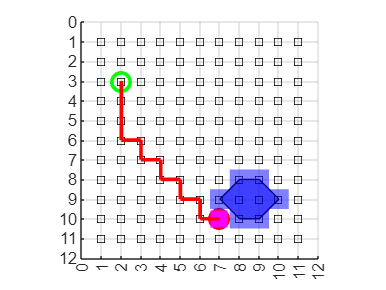

hold on;
for k = 1:size(visit, 1)-1
    plot([visit(k, 2)-1, visit(k+1, 2)-1],[visit(k, 1)-1, visit(k+1, 1)-1], 'r-', 'LineWidth', 2);
end
hold off;